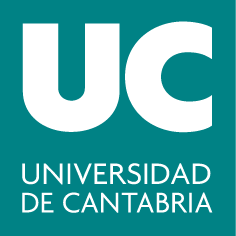

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Métodos Matemáticos en la Ingeniería**

**Bloque II: Métodos Numéricos**

# **3-1. Interpolación**

#### Polinomios en MATLAB

En MATLAB, el tratamiento de polinomios se realiza de manera eficiente utilizando vectores para representar los coeficientes del polinomio, comenzando desde el coeficiente del término de mayor grado hasta el coeficiente del término independiente: `p = [a_n, a_{n-1}, ..., a_1, a_0];`

**Ejercicio:** Define en MATLAB los siguientes polinomios:

- 
$$$p(x) = x^5 +  3x^4 -23x^3  -51x^2 + 94x  $$$


- 
$$$p
(x) = x^3 -6x^2 + 11(x-6) $$$


- 
$$$p(x) = x^4   -13x^3   + 220x -400 $$$


- 
$$$p(x)= x^3   -2x -1 $$$


Para comprobar los resultados:

ejemplo_polinomios

Ir a "ejemplo_polinomios"

Las siguientes funciones permiten realizar una amplia gama de operaciones con polinomios en MATLAB, facilitando la manipulación y análisis de estos:

- [`poly`](https://es.mathworks.com/help/matlab/ref/poly.html): Construye polinomios con raíces específicas.

r = [1, 2, 3];
p = poly(r)  % Crea el polinomio (x-1)(x-2)(x-3)

- [`polyval`](https://es.mathworks.com/help/matlab/ref/polyval.html): Evalúa un polinomio.

p = [2, 3, -1, 5];  % Polinomio 2x^3 + 3x^2 - x + 5
x = 2;
y = polyval(p, x)  % Evalúa el polinomio en x = 2

- [`polyder`](https://es.mathworks.com/help/matlab/ref/polyder.html): Diferenciación polinomial.

p = [2, 3, -1, 5];  % Polinomio 2x^3 + 3x^2 - x + 5
dp = polyder(p)  % Derivada del polinomio

 - [`conv`](https://es.mathworks.com/help/matlab/ref/conv.html): Multiplicación de polinomios.

p1 = [1, 2, 1];  % Polinomio x^2 + 2x + 1
p2 = [1, -1];    % Polinomio x - 1
p3 = conv(p1, p2)  % Resultado de (x^2 + 2x + 1) * (x - 1)

 - [`deconv`](https://es.mathworks.com/help/matlab/ref/deconv.html): División de polinomios.

p1 = [1, -3, 2];  % Polinomio x^2 - 3x + 2
p2 = [1, -1];     % Polinomio x - 1
[q, r] = deconv(p1, p2)  % División de p1 entre p2, q es el cociente y r es el residuo

- [`roots`](https://es.mathworks.com/help/matlab/ref/roots.html): Encuentra raíces de polinomios.

p = [2, 3, -1, 5];  % Polinomio 2x^3 + 3x^2 - x + 5
r = roots(p)  % Encuentra las raíces del polinomio

La función `roots` utiliza el concepto de valores propios para encontrar las raíces de un polinomio.

## 3.1. Interpolación y aproximación polinomial

Existen dos métodos generales para el ajuste de curvas:

#### Interpolación de Lagrange

El polinomio de interpolación de Lagrange es simplemente una re-formulación del polinomio de Newton que evita el cálculo de las diferencias divididas.

Dados $$n + 1$$ puntos distintos$ $\{x_0, x_1,\ldots, x_n \}$$ del intervalo $$[a;
	b]$$ y una 	función $$f : [a; b] \rightarrow \mathbb{R}$$, se dice que un polinomio $$p$ $es el **polinomio de interpolación de Lagrange** de la función $$f$ $en los nodos citados si $$p$$ es de grado  $$ \leq n$$ y $$p(x_i) = f(x_i) = y_i$$ para cada $$0 \leq i \leq n$$.

	
$$p_n (x) = \sum_{i=0}^n L_i(x)y_i, \quad L_i(x) = \prod_{j=0, \; j\neq i}^n
	\frac{x-x_j}{x_i - x_j}$$$$


A los polinomios $$L_i$ $se les llama **polinomios básicos de Lagrange.**

1. [$$n=1$$] Interpolación lineal: $
		
		$$p_1 (x)= \frac{x-x_1}{x_0 - x_1}y_0 + \frac{x-x_0}{x_1 - x_0}y_1 $$$

2. [$n=2$] Interpolación cuadrática: $$$p_2(x) = \frac{(x-x_1)(x-x_2)}{(x_0 - x_1)(x_0 - x_2)}y_0 +
		\frac{(x-x_0)(x-x_2)}{(x_1 - x_0)(x_1 - x_2)}y_1+ \frac{(x-x_0)(x-x_1)}{(x_2
			- x_0)(x_2 - x_1)}y_2$$$

**Ejercicio 3.1: **Halla los polinomios de Lagrange de grado  2 para los siguiente datos:

- 
$$$x_0 = -1$, $x_1 = 0$, $x_2 = 1$; $f_0 =3$, $f_1 = 2$, $f_2 = 5$;$$


- 
$$ $x_0= 1$, $x_1 = 2$, $x_2 = 4$; $f_0 =3$, $f_1 = 4$, $f_2 = 6$.$$


*Una posible implementación del método de Lagrange:*

En muchos casos, es más útil conocer los coeficientes del polinomio interpolador en lugar de solo los valores en puntos específicos.  

**Ejercicio (3.1):** Determinamos los coeficientes de los  polinomios de Lagrange para los siguiente datos:

- 
$$$x_0 = -1$, $x_1 = 0$, $x_2 = 1$; $f_0 =3$, $f_1 = 2$, $f_2 = 5$;$$


- 
$$ $x_0= 1$, $x_1 = 2$, $x_2 = 4$; $f_0 =3$, $f_1 = 4$, $f_2 = 6$.$$


1. Definimos los datos:

clear all
x = [-1, 0, 1];    % vector-fila
y = [3, 2, 5]; 

2. Calculamos los polinomios básicos de Lagrange:

w = length(x); % Número de nodos de interpolación
n = w - 1;     % Grado del polinomio interpolador
L = zeros(w, w);

% Calcular los polinomios básicos de Lagrange L_k(x)
for k = 1:n+1
    V = 1;
    for j = 1:n+1
        if k ~= j
            % Multiplicar por el factor (x - x(j)) y dividir por (x(k) - x(j))
            V = conv(V, poly(x(j))) / (x(k) - x(j));
        end
    end
    L(k, :) = V;
end
L

3. Calcular el polinomio interpolador de Lagrange como una combinación lineal de los polinomios básicos, ponderados por los valores y:

   p = y * L

4. Representamos el polinomio:

f1 = @(x) polyval(p,x);
plot(x,y,'r*') % los puntos
hold on
fplot(f1,[x(1), x(end)],'b-')
grid on
legend ('Datos','p_4(x)')
hold off

Función  que calcula los coeficientes del polinomio interpolador de Lagrange:

**Errores de la interpolación**

El error de truncamiento en la serie de Taylor:


$$$$R_n = \frac{|f^{(n+1)}(\xi)|}{(n+1)!}(x_{i+1} - x_{i})^n$$$$


Para un polinomio de interpolación de$ $n$$-ésimo grado:


$$$$R_n = \frac{|f^{(n+1)}(\xi)|}{(n+1)!}(x - x_0)(x-x_1)\ldots (x - x_n)$$$$


Supongamos que la función $$f$$ es $$n + 1$$ veces derivable en el intervalo $$[a;
b]$$  y que $$f^{(n+1)}$$ es una función continua, entonces una cota del error de interpolación de Lagrange viene dada por la expresión


$$$$|f(x)-f_n(x)| \leq \max_{\xi \in [a;b]} |f^{(n+1)}(\xi)| \frac{\left|
	\prod_{i=0}^n (x-x_i)\right|}{(n+1)!}$$$$


**Ejercicio 3.2:**

Sea $ $f(x) = \cos(x)$ $ definida en el intervalo $$[0,\, 1.2]$$. Construye los polinomios de Lagrange usando los siguientes nodos de interpolación:

-  $$x_0 = 0$, $x_1 = 1.2$$ (Polinomio interpolador lineal);

- $ $x_0 = 0$, $x_1 = 0.6$, $x_2 = 1.2$ $(Polinomio interpolador cuadrático);

-  $$x_0 = 0$, $x_1 = 0.4$, $x_2 = 0.8$, $x_3 = 1.2$$ (Polinomio interpolador cúbico).

		En cada caso, determina la cota del error.

`1. `Polinomio Interpolador Lineal ($$n=1$$)

Nodos:  $$x_0 = 0, x_1 = 1.2$$. 

Valores: $ $f_0 = \cos(0) = 1$; \quad $f_1 = \cos(1.2) \approx 0.3624$$

clearvars
x = [0, 1.2];
y = cos(x)

Construcción del Polinomio $$P_1(x)$$


$$$L_0(x) = \frac{x-x_1}{x_0-x_1} = -\frac{x-1.2}{1.2}; \quad 
	L_1(x)= \frac{x-x_0}{x_1-x_0} = \frac{x}{1.2}$$$
	
$$P_1(x) = 1 \cdot \left(-\frac{x-1.2}{1.2}\right) + 0.3624 \cdot \left(\frac{x}{1.2}\right) 
	= {1 - 0.5314x}$$$


% podemos obtener el mismo resultado usando el algoritmo implemetado para
% la interpolación de Lagrange:
p = poly_lagrange(x,y)

Cota del Error para $$P_1(x)$$:

- Derivada: $$n=1$$, necesitamos $$f''(x) = -\cos(x)$$. 

- Cálculo de $$M_2 = \max_{\xi \in [a;b]} |f^{(n+1)}(\xi)| = \max_{\xi \in [0, 1.2]} |-\cos(\xi)| $$:

-  El máximo ocurre en $$\xi=0$$, donde $$\cos(0)=1$$. Así, $$M_2 = 1}$$. 

- Maximizar $$|(x-x_0)(x-x_1)|$$: Buscamos el máximo de $$|x(x-1.2)|$$ en $$[0, 1.2]$$. El máximo de esta parábola ocurre en el vértice, $$x = 0.6$$. El valor es $$|0.6(0.6-1.2)| = |-0.36| = 0.36$$. 


$$ E_1 \le \frac{M_2}{2!} \max|x(x-1.2)| = \frac{1}{2} \cdot 0.36 = {0.18} $$


Con MATLAB (utilizamos el cálculo simbólico):

syms s real
f(s) = cos(s);
a = 0; b = 1.2;         % intervalo de interpolación
n = length(x)-1         % Grado del polinomio interpolador
derivada = diff(f,n+1)  % (n+1)-ésima derivada

interval = linspace(a, b, 100); % 100 puntos en el intervalo [a,b]
derivada_values = double(derivada(interval));
M = max(abs(derivada_values)) %  máximo de los valores de la derivada

polinomio(s) = prod(s-x)
polinomio_values = double(polinomio(interval));
max_pol = max(abs(polinomio_values))
E = M*max_pol/factorial(n+1)

Resuelve los ejercicios 3.3. - 3.6

% escribe el código aquí





A la vista de la fórmula del error dada por el teorema anterior, es natural plantearse la elección de los nodos$ $\{x_i\}_{i=0}^n$$ de forma que la cantidad $$$\max_{x \in[a;b]}\left| \prod_{i=0}^n (x-x_i)\right| \rightarrow \min$$$

Esto se consigue tomando los llamados **nodos de Chebyshev**:

	
$$$$x_i = \frac{a+b}{2} + \frac{b-a}{2} \cos \frac{(2i+1)\pi}{2(n+1)}, \quad 0
	\leq i \leq n$$$$


Con esta elección de los nodos se tiene $$\max_{x \in[a;b]}\left| \prod_{i=0}^n (x-x_i)\right| =
\frac{(b-a)^{n+1}}{2^{2n+1}}$.$

**Ejercicio:** Implementa el código para calcular $n$ ($n= 1, 2,...$) nodos de Chebyshev en el intervalo $[0,\,1]$ en el orden ascedente.

clear all
a = 0;
b = 1;
n = 5;

% escribe  el código aquí





Para comprobar los resultados:

x2 = chebyshev(a,b,n)
plot(x2,zeros(1,n),'r*')
grid on

**Ejercicio (3.7):**  Dada la función de Runge:

	
$$$$f: [-5; +5] \rightarrow \mathbb{R}, \quad f(x) = \frac{1}{1+x^2}$$$$


- Halla los polinomios interpoladores de Lagrange de grado 5, 10 y 20, respectivamente, que interpolan a $$f$$ en puntos igualmente espaciados del intervalo $$[-5; +5]$$.

- Representa gráficamente la función y los correspondientes polinomios interpoladores.

- Compara los resultados con la interpolación usando los nodos de Chebyshev.

% escribe  el código aquí




#### Interpolación polinomial a trozos

-  Un procedimiento alternativo consiste en colocar polinomios de grado inferior en subconjuntos de los datos. Tales polinomios conectores se denominan **trazadores** o **splines**.

-  Las curvas de tercer grado empleadas para unir cada par de datos se llaman trazadores cúbicos. Esas funciones se pueden construir de tal forma que las conexiones entre ecuaciones cúbicas adyacentes resulten visualmente suaves.

El objetivo en los trazadores cúbicos es obtener un polinomio de tercer grado para cada intervalo entre los nodos:


$$$$S_i(x) = a_i + b_i (x-x_i) + c_i (x-x_i)^2 + d_i (x-x_i)^3$$$$


Longitud del intervalo $$i$$ es  $$h_i = x_{i+1}-x_i$$.

$$n+1$$ datos, $$n$$ intervalos $ \to 4n $ incógnitas $$\rightarrow$ $4n$$ condiciones:

- Los valores de la función deben ser iguales en los nodos interiores ($$2n - 2$$ condiciones):


$$$S_i(x_i) = f_i: \qquad \qquad a_i = f_i, \quad i = 1, \ldots, n$$$



$$$S_i(x_{i+1}) = f_{i+1}: \qquad  a_i + b_i h_i + c_i h_i^2 + d_i h_i^3 =
		f_{i+1}, \quad i = 1, \ldots, n$$$


- La primera y última función deben pasar a través de los puntos extremos (2 condiciones)

- Las primeras derivadas en los nodos interiores deben ser iguales ($n-1$ condiciones)


$$$S_i'(x_{i+1}) = S_{i+1}'(x_{i+1}): \quad b_i + 2c_ih_i + 3d_i h_i^2 = b_{i+1},
		\quad i = 1,\ldots, n-1$$$


- Las segundas derivadas en los nodos interiores deben ser iguales ($n-1$ condiciones)


$$	$S_i''(x_{i+1}) = S_{i+1}''(x_{i+1}): \quad 2c_i + 6d_ih_i = 2c_{i+1} \quad i =
		1,\ldots, n-1$$$


- Las segundas derivadas en los nodos extremos son cero  (2 condiciones)


$$$S_1''(x_1) = 0 : \quad 2c_1 = 0; \qquad S_{n}''(x_{n+1}) = 0 : \quad 2c_{n} + 6d_{n} h_{n} = 0$$$
 

Así, $ $a_i$$ son conocidos: $$ a_i = f_i$$; despejamos  $$b_{i} = \frac{f_{i+1}-f_{i}}{h_i} - \frac{2}{3} c_i h_i -
	\frac{1}{3}c_{i+1}h_i$$,       $$d_i = \frac{c_{i+1} - c_i}{2h_i}$$.

Se obtiene el siguiente sistema tridiagonal para resolver:


$$$$h_{i-1} c_{i-1} + 2(h_{i-1}+h_i)c_i + h_{i} c_{i+1} = 6 \left(
\frac{f_{i+1}-f_i}{h_{i} }  - \frac{f_{i}-f_{i-1}}{h_{i-1} }\right)$$$$


El comando `spline` en MATLAB ajusta un polinomio cúbico a trozos a un conjunto de puntos de datos.

- x: Vector de coordenadas $\( x \)$ de los puntos de datos.

- y: Vector de coordenadas $\( y \)$ de los puntos de datos.

- pp: Estructura de tipo ``pp`` (piecewise polynomial) que contiene la representación del polinomio cúbico por tramos.

- xq: Vector de puntos en los que se desea evaluar el polinomio interpolante.

- yq: Devuelve los valores interpolados en los puntos especificados por xq.

**Ejemplo:** 

clear all
x = linspace(0,4,10);
y = 1./cos(x);

% Calcular el polinomio de interpolación cúbica
pp = spline(x, y)
% Evaluar el polinomio en puntos nuevos
xq = linspace(0, 4, 100);
yq = ppval(pp, xq); % OJO! no es 'polyval'
% Graficar los puntos originales y la interpolación
plot(x, y, 'r*', xq, yq, 'b-');
grid on
legend('Datos', 'Trazador cúbico');

#### Regresión en mínimos cuadrados

Cuando los datos tienen errores sustanciales, la interpolación polinomial es inapropiada y puede dar resultados poco satisfactorios cuando se utiliza para predecir valores intermedios. Una estrategia más apropiada en tales casos consiste en obtener una función de aproximación que se ajuste a la forma o a la tendencia general de los datos, sin coincidir necesariamente en todos los puntos.

Se debe encontrar algún criterio para establecer una base para el ajuste. Una forma de hacerlo es obtener una curva que minimice 	la discrepancia entre los puntos y la curva. Una técnica para lograr tal objetivo, llamada **regresión por mínimos cuadrados**.

Dados $$n + 1$ $ puntos distintos $$\{x_0, x_1, \ldots, x_n\}$$ del intervalo $[a,b]$, una función $$f : [a; b]\rightarrow \mathbb{R}$$, el problema de mínimos cuadrados consiste en resolver

	
$$
	$$\sum_{j=0}^n \left(f(x_j) - p(x_j)\right)^2 \rightarrow \min$$$$


**Regresión lineal**: ajustar una línea recta a un conjunto de observaciones definidas por puntos:$ $(x_1, y_1)$, $(x_2, y_2)$, $\ldots$, $(x_n, y_n)$$.

Ecuación de una recta: $$y = a_0 + a_1x + e$$,  donde $$e$ $es el error o residuo: $e = y - (a_0 + a_1x)$.

Criterio para un "mejor" ajuste: 	$$S_r = \sum_{i=1}^n e_i^2 = \sum_{i=1}^n (y_i - a_0 - a_1x_i)^2 \rightarrow
	\min$$

Para determinar los valores de $$a_0$ y $a_1$, $S_r$$ se deriva con respecto a cada uno de los coeficientes:


$$$$\frac{\partial S_r}{\partial a_0} = -2 \sum (y_i-a_0 - a_1x_i),
\qquad\frac{\partial S_r}{\partial a_1} = -2 \sum (y_i-a_0 - a_1x_i)x_i$$$$


Al igualar estas derivadas a cero, se dará como resultado un $$S_r$$ mínimo:

$$$\begin{cases} \sum y_i - n a_0 - a_1\sum x_i
= 0
\\ \sum x_i y_i - a_0 \sum x_i - a_1 \sum x_i^2
= 0
\end{cases}$$$, de donde


$$
$$a_1 = \frac{n \sum x_i y_i -\sum x_i \sum y_i}{n \sum x_i^2 - \left(\sum x_i
	\right)^2}, \quad
a_0 = \frac{1}{n}\left(\sum y_i -a_1 \sum x_i \right)$$$$


**Ejercicio (3.8)**: Ajuste a una línea recta los valores (x,y):

clear all
x = 1:7;
y = [0.5 2.5 2.0 4.0  3.5  6.0  5.5];
plot(x,y,'r*')
grid on

	Se calculan las siguientes cantidades:

n = length(x);
sx = sum(x);
sy = sum(y);
sxy = x*y';
sx2 = x*x';	

 $$n= 7$, $\sum x_i = 28$, $\sum y_i = 24$$, $$\sum x_i y_i= 119.5$, $\sum x_i^2 = 140$$

Entonces, 


$$$$\begin{cases} \sum y_i - n a_0 - a_1\sum x_i
= 0
\\ \sum x_i y_i - a_0 \sum x_i - a_1 \sum x_i^2
= 0
\end{cases}
\Rightarrow 
	\begin{cases} 24 -7 a_0 - 28a_1  = 0
	\\ 119.5 - 28 a_0  - 140a_1  = 0
	\end{cases}
\Rightarrow 
	\begin{cases} 7 a_0 + 28a_1  = -24 
	\\   28 a_0  +140a_1  = -119.5
	\end{cases}$$


Resolvemos este sistema:

A = [n sx; sx sx2]; % matríz del sistema
b = [sy; sxy];
a = A\b

Se obtienen los coeficientes: $	$a_1 = 0.8392857, \quad a_0 = 0.07142857$$. La recta de regresión será:


$$y =  0.8392857x +  0.07142857$$$


recta = @(x) a(2)*x+a(1);
hold on
fplot(recta,[x(1), x(end)],'b-')
legend('Datos', 'Regresión lineal')
hold off

**Regresión polinomial**

El procedimiento de mínimos cuadrados se puede extender fácilmente al ajuste de datos con un polinomio de grado superior. Por ejemplo, suponga que ajustamos un polinomio de segundo grado o cuadrático:


$$$$y = a_0 + a_1 x + a_2 x^2 +e $$$$


La suma de los cuadrados de los residuos es


$$$$S_r = \sum_{i=1}^n \left(y_i- a_0 - a_1 x_i - a_2 x_i^2\right)^2\to \min$$$$


La derivada de $$S_r$$ con respecto a cada uno de los coeficientes desconocidos del polinomio:


$$$$
\begin{cases}
\frac{\partial S_r }{\partial a_0} = -2 \sum \left(y_i - a_0 - a_1 x_i - a_2
x_i^2\right) 
\\
\frac{\partial S_r }{\partial a_1} = -2 \sum  \left[ \left(y_i - a_0 - a_1 x_i -
a_2 x_i^2\right)x_i\right]
\\
\frac{\partial S_r }{\partial a_2} = -2 \sum \left[ \left(y_i - a_0 - a_1 x_i -
a_2 x_i^2\right)x_i^2\right]
\end{cases}
$$$$


Estas ecuaciones se igualan a cero y se re-ordenan:


$$\begin{cases}
n a_0  +  \left(\sum x_i \right) a_1 +  
\left(\sum x_i^2 \right)a_2 =   \left(\sum y_i \right)
\\
\left(\sum x_i \right) a_0+ \left(\sum x_i^2
\right) a_1+  \left(\sum x_i^3 \right) a_2
=  \left(\sum x_i y_i \right)
\\
\left(\sum x_i^2 \right) a_0+ \left(\sum x_i^3
\right) a_1+ \left(\sum x_i^4 \right)a_2
= \left(\sum x_i^2 y_i \right)
\end{cases}
$$
$$


**Ejercicio 3.9**: Ajustamos a un polinomio de segundo grado los datos:

clear all
x = 0:5;
y = [2.1  7.7    13.6    27.2   40.9   61.1];
plot(x,y,'r*')
grid on

Calculamos los coeficientes del sistema:

m = 2; % grado del polinomio

Para simplificar los cálculos, evaluamos $\(x^0\), \(x^1\) y \(x^2\)$ en una sola línea:

x'.^[0:m] 

Si ahora sumamos los elementos en cada columna, obtenemos $n, \sum x,\sum x^2$, respectivamente:

A1 = sum(x'.^[0:m] )

Son los coeficientes de la primera ecuación. De manera similar, podemos calcular los coeficientes de la segunda y tercera ecuaciones:

A2 = sum(x'.^[1:m+1]);
A3 = sum(x'.^[2:m+2]);
A = [A1; A2; A3]

Se puede obtener el mismo resultado usando un bucle. Hazlo tú. 

% escribe aquí el código



Para calcular el vector $b$ hacemos lo mismo:

b = sum(y'.*(x'.^[0:m]))' 

Calculamos los coeficientes:

a = A\b


$$	$a_0 = 2.47857$, $a_1 = 2.35929$, $a_2 = 1.86071$$$


Para evaluar el polinomio podemos utilizar el comando `polyval.` Para ello, debemos invertir el orden de los coeficientes:

a = flipud(a)

Ahora podemos representar la curva:

recta = @(x) polyval(a,x);
hold on
fplot(recta,[x(1), x(end)],'b-')
legend('Datos', 'Regresión cuadrática')
hold off

En el caso del polinomio de $m$-ésimo grado:


$$$$
\begin{cases}
(n)  a_0 & + & \left(\sum x_i \right) a_1 & + & 
\ldots &  \left(\sum x_i^{m} \right)a_m& = &  \left(\sum y_i
\right)
\\
\left(\sum x_i \right)  a_0 & + & \left(\sum x_i^2
\right)a_1& + & \ldots &  \left(\sum x_i^{m+1}
\right)a_m & = &  \left(\sum x_i y_i \right)
\\
\ldots &  & & & & & 
\\
\left(\sum x_i^{m} \right) a_0 & + & \left(\sum x_i^{m+1}
\right) a_1 & + & \ldots & \left(\sum x_i^{2m}
\right) a_m & = &  \left(\sum x_i^{m} y_i \right)
\end{cases}
$$$$


**Ejercicio**: Escribe un programa que calcule los coeficientes del polinomio de $m$-ésimo grado que se ajuste a los datos $(x_i, y_i)$). La función debe devolver un vector con los coeficientes del polinomio en orden descendente de potencias.

clear all
x = 0:5;
y = [2.1  7.7    13.6    27.2   40.9   61.1];
plot(x,y,'r*')
grid on
m = 3; % grado del polinomio

#### Interpolación y regresión con MATLAB

MATLAB proporciona diversas funciones para realizar interpolación, siendo las más comunes `interp1`, `spline` y `polyfit`.

- La función [`interp1`](https://es.mathworks.com/help/matlab/ref/interp1.html) en MATLAB se utiliza para realizar interpolación unidimensional en un conjunto de datos:

` -``x`: Vector de coordenadas x de los puntos de datos conocidos.

  - y: Vector de valores y correspondientes a las coordenadas x.

` -``xq`: Vector de puntos donde se desea realizar la interpolación.

` -``yq`: Valores interpolados en los puntos xq.

- El comando [`spline`](https://es.mathworks.com/help/matlab/ref/spline.html) en MATLAB ajusta un polinomio cúbico a trozos a un conjunto de puntos de datos.

- x: Vector de coordenadas $\( x \)$ de los puntos de datos.

- y: Vector de coordenadas $\( y \)$ de los puntos de datos.

- p: Estructura de tipo ``p`` (piecewise polynomial) que contiene la representación del polinomio cúbico por tramos.

- La función [`polyfit`](https://es.mathworks.com/help/matlab/ref/polyfit.html) en MATLAB se utiliza para realizar ajustes polinómicos a un conjunto de datos. 

- x: Vector de coordenadas $\( x \)$ de los puntos de datos.

- y: Vector de coordenadas $\( y \)$ de los puntos de datos.

- n: Grado del polinomio.

- p: Vector de coeficientes del polinomio de grado nnn en orden descendente de potencias.

La función `polyfit` calcula los coeficientes de un polinomio $p(x)$ de grado$n$ que minimiza el error cuadrático entre los valores del polinomio y los datos proporcionados. Los coeficientes se devuelven en un vector, comenzando con el coeficiente de la potencia más alta.

La función `polyfit` también se puede utilizar para resolver el problema de interpolación, ya que el polinomio de grado $n$ que se ajusta a $n+1$ puntos es único.

**Ejercicio (3.9): **

clear all
x = 0:5;
y = [2.1  7.7    13.6    27.2   40.9   61.1];
plot(x,y,'r*')
grid on
m = 3; % grado del polinomio
p = polyfit(x,y,m);
recta = @(x) polyval(p,x);
hold on
fplot(recta,[x(1), x(end)],'b-')
legend('Datos', 'Polinomio interpolador')
hold off

## Bibliografía

- [Chapra S.C.; Canale R. (2015) Métodos Numéricos para Ingenieros. Ed. McGRaw-Hill](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=436963) (Capítulos 17-18)

- [Mathews J.H., Fink K.D. (2000) Métodos Numéricos con MATLAB. Ed. Prentice Hall](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=163396) (Capítulos 4 - 7)

Funciones auxiliares

 Ejemplo de definición de los polinomios:

function [] = ejemplo_polinomios()
p1 = [1 3 -23 -51 94 0];
vect2poly(p1);
disp(p1)
p2 = [1 -6 11 -66];
vect2poly(p2);
disp(p2)
p3 = [1 -13 0 220 -400];
vect2poly(p3);
disp(p3)
p4 = [1 0 -2 -1];
vect2poly(p4);
disp(p4)
end

function [] = vect2poly(v)
n = length(v);
fprintf("\n")
str1 = ["Polinomio: p(x) = ",num2str(v(1)),'x^', num2str(n-1)];
for k = 2:n-1
    if(v(k) >0)
        str1 = [str1, '+',num2str(v(k)),'x^', num2str(n-k)];
    elseif v(k) <0
           str1 = [str1,'-', num2str(-v(k)),'x^', num2str(n-k)];
    end
end
    if(v(n) >0)
        str1 = [str1, '+',num2str(v(n))];
    elseif v(n) <0
           str1 = [str1,'-', num2str(-v(n))];
    end

fprintf("%s",str1)
fprintf("\n")
end

- Polinomios de Lagrange: 

function p = poly_lagrange(x, y)
% x: vector (fila) de nodos de interpolación en el eje x
% y: vector (fila) de valores de la función en los nodos x
% p: vector de coeficientes del polinomio interpolador de Lagrange
    w = length(x); % Número de nodos de interpolación
    n = w - 1;     % Grado del polinomio interpolador

    % Inicializar la matriz L para almacenar los polinomios básicos de Lagrange
    L = zeros(w, w);

    % Calcular los polinomios básicos de Lagrange L_k(x)
    for k = 1:n+1
        V = 1; 
        for j = 1:n+1
            if k ~= j
                % Multiplicar por el factor (x - x(j)) y dividir por (x(k) - x(j))
                V = conv(V, poly(x(j))) / (x(k) - x(j));
            end
        end
        L(k, :) = V;
    end

    % Calcular el polinomio interpolador de Lagrange como una combinación lineal
    % de los polinomios básicos, ponderados por los valores y
    p = y * L;
end

1. Nodos de Chebyshev:

function [x] = chebyshev(a,b,n)
x=[];
for i = 1:n
    x=[ (a+b)/2 + (b-a)/2*cos((2*i-1)*pi/(2*n)), x];
end 
end